clc, clear all, close all;

path = pwd + "/sim_data_15bpm_1-50sw/";
fullpath = join([path, "00_rawvals.csv"], "");
num = readmatrix(fullpath);

ids = ["e280116060000205403ddcdb", "e280116060000209e445f02a"] % sim tags

ids = 1×2 string array
    "e280116060000205403ddcdb"    "e280116060000209e445f02a"


%ids = ["e280116060000205403de047", "e280116060000205403e136b"];
epc = readtable(fullpath).epc96(:);

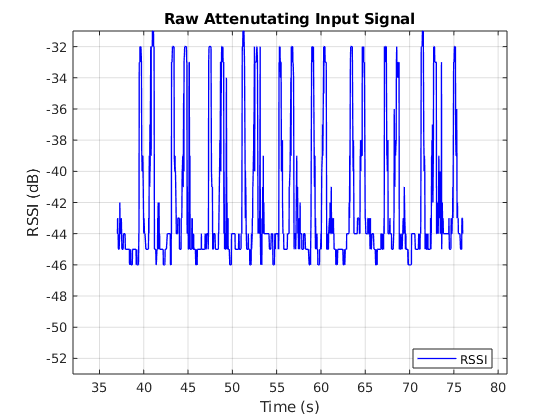


time_main = num(:, 3);
time_main = time_main(epc == ids(1));
rssi_main = num(:, 2);
rssi_main = rssi_main(epc == ids(1));

time_ref = num(:, 3);
time_ref = time_ref(epc == ids(2));
rssi_ref = num(:, 2);
rssi_ref = rssi_ref(epc == ids(2));

min_y = min([min(rssi_main) min(rssi_ref)]);
max_y = max([max(rssi_main) max(rssi_ref)]);

min_x = min(time_main) - 5;
max_x = max(time_main) + 5;

figure;
plot(time_main, rssi_main, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location", "best");
xlim([min_x, max_x]);
ylim([min_y, max_y]);

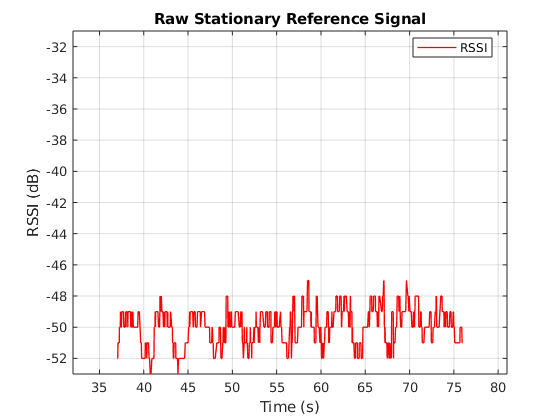


figure;
plot(time_ref, rssi_ref, 'r', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Stationary Reference Signal');
legend('RSSI', "Location", "best");
xlim([min_x, max_x]);
ylim([min_y, max_y]);

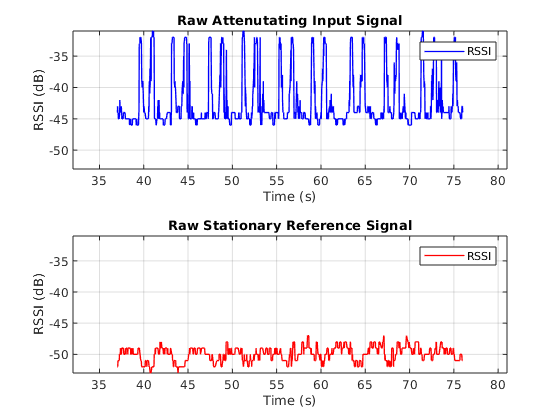


figure;
tiledlayout(2, 1);

ax1 = nexttile;
plot(time_main, rssi_main, 'b', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Attenutating Input Signal');
legend('RSSI', "Location","best");
xlim([min_x, max_x]);
ylim([min_y, max_y]);

ax2 = nexttile;
plot(ax2, time_ref, rssi_ref, 'r', 'linewidth', 1);
xlabel('Time (s)'), ylabel('RSSI (dB)');
grid on, title('Raw Stationary Reference Signal');
legend('RSSI', "Location", "best");
xlim([min_x, max_x]);
ylim([min_y, max_y]);